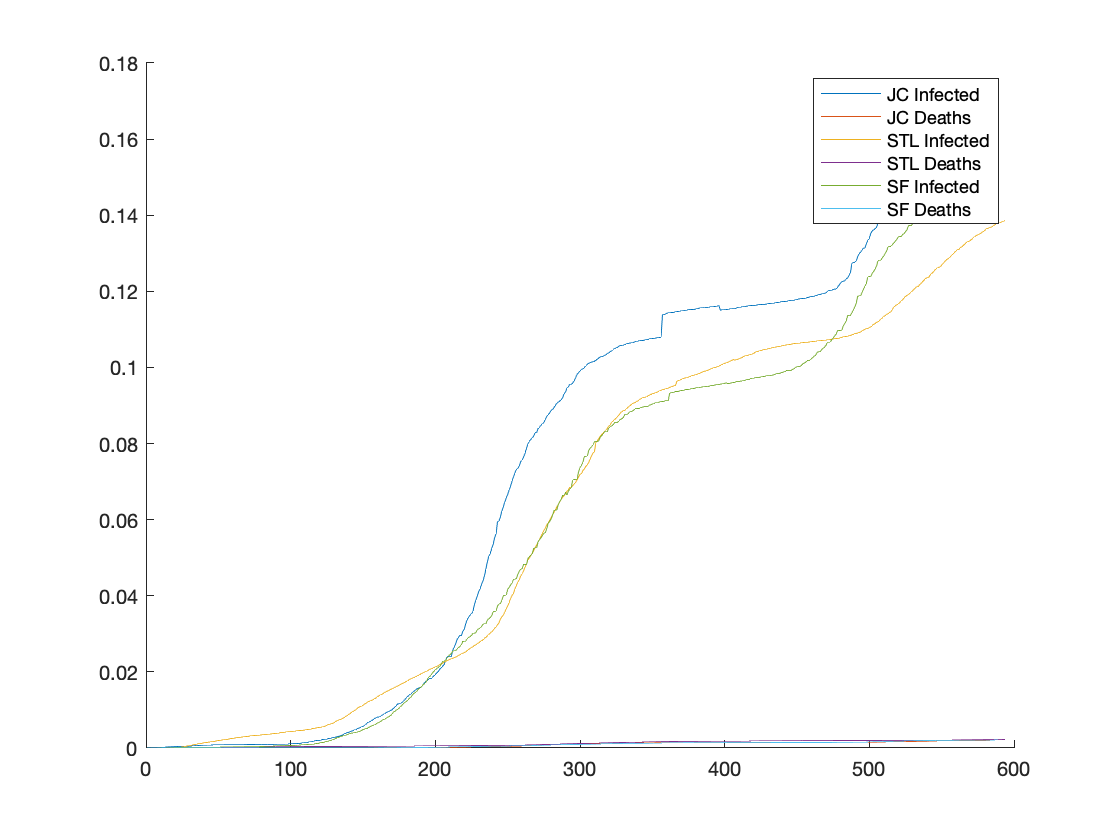

% Here is an example that reads in infection and fatalities from STL City
% and loads them into a new matrix covidstlcity_full
% In addition to this, you have other matrices for the other two regions in question
% DEBUG
base_data = load("COVIDdata.mat");

coviddata = load("COVIDdata.mat");
casedata = coviddata.COVID_MO;
pops = containers.Map({'Jefferson City','St. Louis','Springfield'},[150198,2805473,475220]);
start = 200;
t = 200; % TO SPECIFY
jc_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==1,setdiff(1:4,2));
jc = table2array(jc_data(:,2:3))./pops('Jefferson City');
stl_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==2,setdiff(1:4,2));
stl = table2array(stl_data(:,2:3));
stl = stl./pops('St. Louis');
sf_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==3,setdiff(1:4,2));
sf = table2array(sf_data(:,2:3))./pops('Springfield');
figure;
hold on
plot(jc)
plot(stl)
plot(sf)
legend('JC Infected', 'JC Deaths', 'STL Infected', 'STL Deaths', 'SF Infected', 'SF Deaths')
hold off

coviddata = sf(start:start+t-1,:);


% The following line creates an 'anonymous' function that will return the cost (i.e., the model fitting error) given a set
% of parameters.  There are some technical reasons for setting this up in this way.
% Feel free to peruse the MATLAB help at
% https://www.mathworks.com/help/optim/ug/fmincon.html
% and see the sectiono on 'passing extra arguments'
% Basically, 'sirafun' is being set as the function siroutput (which you
% will be designing) but with t and coviddata specified.
sirafun= @(x)siroutput_full(x,t,coviddata);

## set up rate and initial condition constraints

Set A and b to impose a parameter inequality constraint of the form A*x < b Note that this is imposed element-wise If you don't want such a constraint, keep these matrices empty.

A = [];
b = [];

## set up some fixed constraints

Set Af and bf to impose a parameter constraint of the form Af*x = bf Hint: For example, the sum of the initial conditions should be constrained If you don't want such a constraint, keep these matrices empty.

Af = [];
bf = [];

## set up upper and lower bound constraints

Set upper and lower bounds on the parameters lb < x < ub here, the inequality is imposed element-wise If you don't want such a constraint, keep these matrices empty.

ub = ones(1,9)';
lb = zeros(1,9)';

% Specify some initial parameters for the optimizer to start from
% Inf; Fat; Rec; Vac; Lock; Exit; ILock; Susc; Lock; Inf; Rec; Fat
x0 = [0.02 0.01 0.1 0.1 0.98 0 0.02 0 0]

x0 =     0.0200    0.0100    0.1000    0.1000    0.9800         0    0.0200         0         0



% This is the key line that tries to opimize your model parameters in order to
% fit the data
% note tath you 
options = optimoptions("fmincon","MaxFunctionEvaluations",50000);
x = fmincon(sirafun,x0,A,b,Af,bf,lb,ub,[],options);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


k_infections = x(1)

k_infections = 0.0019

k_fatality = x(2)

k_fatality = 9.1969e-05

k_recover = x(3)

k_recover = 0.0028

k_vac = x(4)

k_vac = 0.0011

% set up initial conditions
ic_susc = x(5);
ic_lock = x(6);
ic_inf = x(7);
ic_rec = x(8);
ic_fatality = x(9);

% Set up SIRD within-population transmission matrix

A = [1-k_infections-k_vac 0 0 0 0; 
    0 0 0 0 0;
    k_infections 0 1-k_recover-k_fatality 0 0; 
    k_vac 0 k_recover 1 0; 
    0 0 k_fatality 0 1];
B = zeros(5,1);

% Set up the vector of initial conditions
x0 = [ic_susc, ic_lock, ic_inf, ic_rec, ic_fatality];

sys_sir_base = ss(A,B,eye(5),zeros(5,1),1);
y = lsim(sys_sir_base,zeros(t,1),linspace(0,t-1,t),x0)

y =     0.4521    0.5109    0.0106    0.5109    0.0005
    0.4507         0    0.0114    0.5114    0.0005
    0.4494         0    0.0122    0.5119    0.0005
    0.4481         0    0.0130    0.5124    0.0005
    0.4468         0    0.0138    0.5129    0.0005
    0.4455         0    0.0146    0.5134    0.0005
    0.4442         0    0.0154    0.5139    0.0005
    0.4429         0    0.0162    0.5144    0.0005
    0.4416         0    0.0170    0.5150    0.0005
    0.4403         0    0.0177    0.5155    0.0005


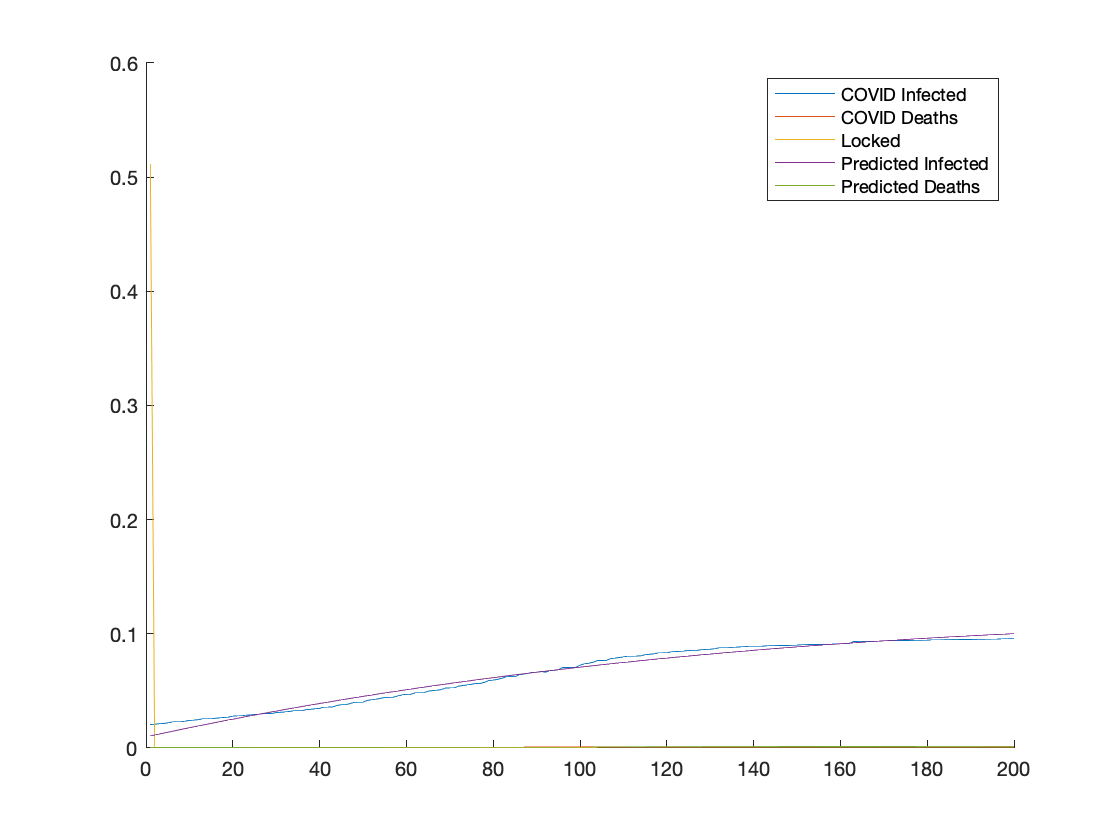


recovered = zeros(size(y(:,3)));
% Assuming COVID takes 7 days to kill / recover, according to CDC

for i=9:length(recovered)
    recovered(i) = coviddata(i-7,1)-coviddata(i-8,1) - (coviddata(i-7,2)-coviddata(i-8,2));
end
recovered = cumsum(recovered);

figure;
hold on;
plot(coviddata)
plot(y(:,2))
plot(y(:,3))
plot(y(:,5))
legend('COVID Infected','COVID Deaths','Locked','Predicted Infected','Predicted Deaths');
hold off

 
% plot(Y);
% legend('S','L','I','R','D');
% xlabel('Time')

% Y_fit = siroutput_full(x,t);
% 
% figure(1);

% Make some plots that illustrate your findings.
% TO ADD

%POLICY
sys_sir_base = ss(A,B,eye(5),zeros(5,1),1);
y = lsim(sys_sir_base,zeros(365,1),linspace(0,364,365),y(t,:))

y =     0.2522         0    0.1002    0.6199    0.0017
    0.2515         0    0.1003    0.6205    0.0017
    0.2507         0    0.1005    0.6210    0.0017
    0.2500         0    0.1007    0.6216    0.0017
    0.2493         0    0.1009    0.6221    0.0017
    0.2485         0    0.1010    0.6227    0.0017
    0.2478         0    0.1012    0.6232    0.0017
    0.2471         0    0.1014    0.6238    0.0017
    0.2464         0    0.1015    0.6243    0.0017
    0.2456         0    0.1017    0.6249    0.0017


figure;
hold on;
plot(y(:,3))
plot(y(:,5))

sol=zeros(365,5);
sol(1,:) = y(1,:);
lastPolicy=[1-k_infections 0 0 0 0; 
    0 0 0 0 0; 
    k_infections 0 1-k_recover-k_fatality 0 0; 
    0 0 k_recover 1 0; 
    0 0 k_fatality 0 1];
for i=2:365
    lastPolicy = sirpolicy(lastPolicy,sol(i-1,:)');
    sol(i,:) = (lastPolicy * sol(i-1,:)')';
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

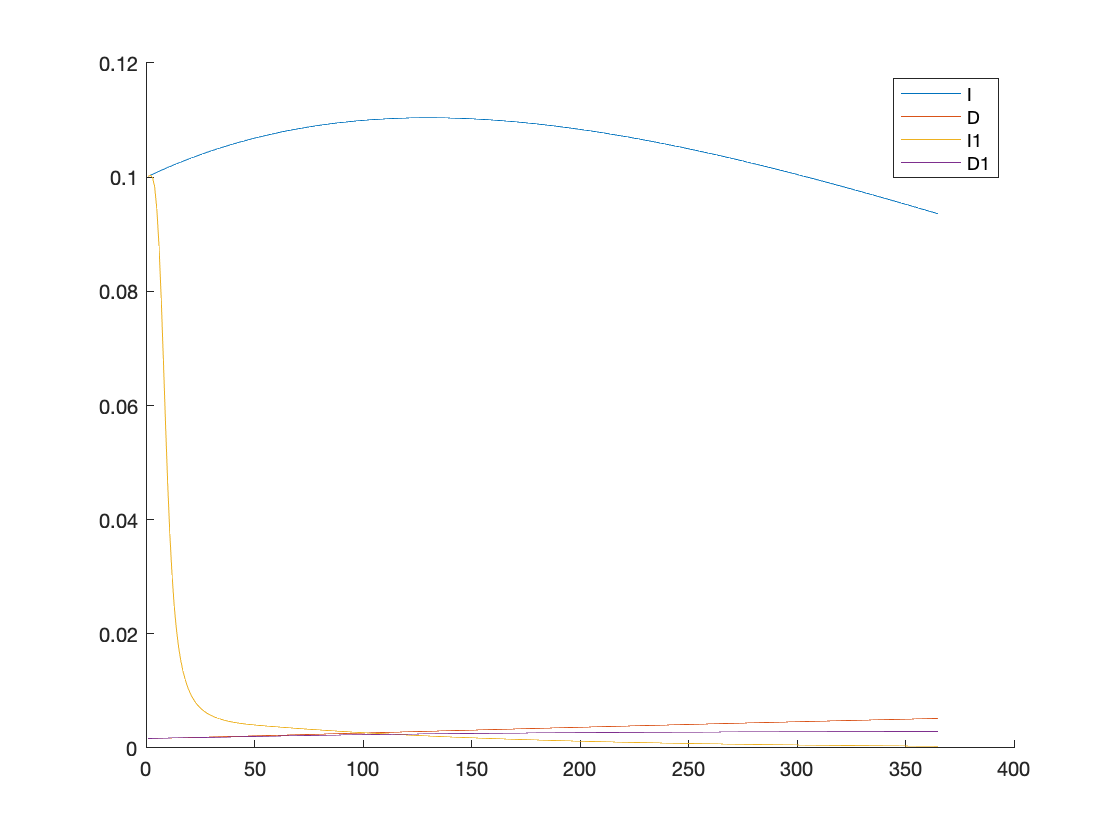

plot(sol(:,3));
plot(sol(:,5));
xlabel("Time");
ylabel("Fraction Population");
legend('I','D','I1','D1');
 hold off